# NB-IoT simulation

## transmission

clear
%base message
dataLength=12*21*2;
messageBits= randi([0 1],dataLength,1)

messageBits =      0
     0
     0
     1
     0
     1
     0
     0
     1
     0


% messageBits=ones(dataLength,1)
%map bits to qpsk symbols
messageInts=bit2int(messageBits,2)% grouped by 2 bits, converted to dec

messageInts =      0
     1
     1
     0
     2
     0
     1
     0
     3
     1


symbolMap=[1+1i, -1+1i, 1-1i, -1-1i] / sqrt(2); %normalized QPSK constellation points
messageSymbols = zeros(size(messageInts, 1), 1);
for k = 1:size(messageInts, 1)
    idx = messageInts(k) + 1; %map index
    messageSymbols(k) = symbolMap(idx); %symbolmap
end
messageSymbols

messageSymbols =    0.7071 + 0.7071i
  -0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 - 0.7071i
   0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i


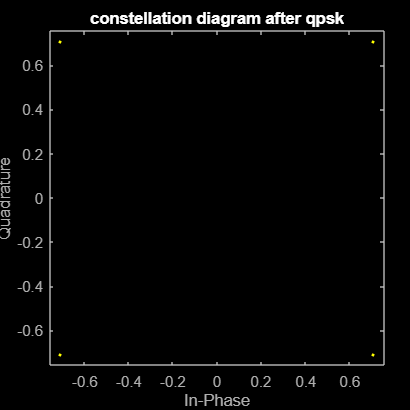

%plot scatterplot
figure;
scatterplot(messageSymbols);
title('constellation diagram after qpsk');

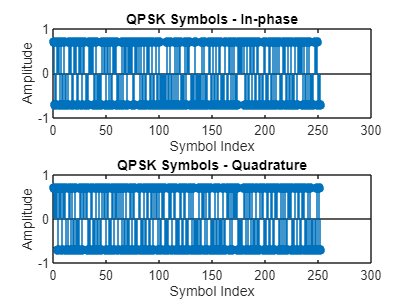


%plot time domain
figure;
subplot(2,1,1);
stem(real(messageSymbols), 'filled');
title('QPSK Symbols - In-phase');
xlabel('Symbol Index');
ylabel('Amplitude');
subplot(2,1,2);
stem(imag(messageSymbols), 'filled');
title('QPSK Symbols - Quadrature');
xlabel('Symbol Index');
ylabel('Amplitude');

% %ofdm
% % PARALLEL TO SERIAL STAP LOOPT FOUT
% numSC=12;% # subcarriers
% cpLen=3;%cyclic prefix length
% numSym=7;% # ofdm symbols
% bandwidth=180e3;
% SCS=15e3;
% carrierFreq=890e6;
% 
% numSymbolsRequired = numSC * numSym;
% if length(messageSymbols) < numSymbolsRequired
%     error('Not enough symbols to fill the OFDM frame');
% end
% 
% ofdmSymbolsMatrix = reshape(messageSymbols(1:numSymbolsRequired), numSC, numSym);%reshape into 12 carrier x7 symbols frame in freq domain
% 
% timeDomainSymbols = ifft(ofdmSymbolsMatrix, numSC);%time domain frame, 12 samples
% 
% cpSymbols = [timeDomainSymbols(end-cpLen+1:end, :); timeDomainSymbols];
% 
% txSignalOFDMA = cpSymbols(:);% (:) reshapes matrix into column
% 
% 
% 
% figure
% scatterplot(txSignalOFDMA)
% title('constellation diagram after OFDM');
% 
% % Plot the time domain signal
% figure;
% subplot(2,1,1);
% plot(real(txSignalOFDMA));
% title('OFDM Signal Time Domain');
% xlabel('Sample Index');
% ylabel('Amplitude');
% 
% [pxx,f] = pspectrum(txSignalOFDMA);
% subplot(2,1,2);
% plot(f,pow2db(pxx))
% grid on
% title('OFDM Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')


numSC=12;% # subcarriers
numSym=21;% # ofdm symbols
SCS=15e3;
BW=SCS*numSC;
samplingRate = numSC * SCS;
symbolDuration = 1 / SCS; % Duration of one OFDM symbol (T=1/FS = 1/SCS)
SPS = round(samplingRate * symbolDuration);
t = (0:SPS-1) / samplingRate; %time vector
ofdmSignal = zeros(1, numSym * SPS);

cpLen=round(SPS/4);


ofdmMatrix = zeros(numSC,numSym);%12x7 in nbiot
for symbolIdx =1:numSym
    ofdmMatrix(:,symbolIdx)=messageSymbols((symbolIdx-1)*numSC+1:numSC*symbolIdx);
end
ofdmMatrix%every column represents 12 carriers for 1 ofdm symbol

ofdmMatrix =    0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i
  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i
  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.70

%the entire column/symbol is transmitted at once at different freq

timeDomainSymbolMatrix = ifft(ofdmMatrix, numSC);%time domain frame, 12 samples per symbol
%every colum contains the sample of the symbol over time, the column
%elements are transmitted one by one
cp=timeDomainSymbolMatrix(end-(cpLen-1):end,:)

cp =    0.1179 - 0.1179i   0.1179 + 0.1179i   0.0000 - 0.3536i  -0.1179 + 0.1179i  -0.3536 + 0.0000i   0.0000 + 0.3536i   0.0000 + 0.2357i   0.2357 - 0.1179i   0.0000 + 0.3536i  -0.2357 - 0.1179i   0.0000 + 0.4714i   0.2357 - 0.1179i  -0.4714 + 0.1179i  -0.2357 + 0.0000i  -0.1179 + 0.1179i  -0.2357 - 0.1179i   0.1179 + 0.1179i   0.3536 - 0.2357i   0.1179 - 0.2357i  -0.1179 + 0.1179i   0.0000 + 0.0000i
   0.0000 + 0.3220i  -0.2515 - 0.3809i   0.0000 + 0.4398i  -0.0863 + 0.3220i  -0.0747 + 0.0431i   0.1610 + 0.0431i   0.3378 - 0.3809i  -0.0431 + 0.0431i   0.3651 + 0.2788i   0.0000 + 0.1179i  -0.0431 - 0.2788i  -0.1610 - 0.2788i  -0.0747 - 0.1610i   0.1179 - 0.1179i  -0.0431 - 0.1610i  -0.1610 + 0.0747i   0.1063 - 0.3967i   0.1610 + 0.0747i   0.3220 + 0.0316i   0.3651 + 0.1610i   0.2788 - 0.3651i
  -0.0863 + 0.0000i   0.0158 - 0.1452i   0.4830 - 0.1610i   0.2041 + 0.1179i   0.0747 + 0.2788i   0.0000 + 0.2357i   0.0158 + 0.1452i  -0.2357 - 0.1179i   0.2357 - 0.1179i   0.3220 + 0.2041i  -0.

timeDomainSymbolMatrix=[cp; timeDomainSymbolMatrix]%add cp

timeDomainSymbolMatrix =    0.1179 - 0.1179i   0.1179 + 0.1179i   0.0000 - 0.3536i  -0.1179 + 0.1179i  -0.3536 + 0.0000i   0.0000 + 0.3536i   0.0000 + 0.2357i   0.2357 - 0.1179i   0.0000 + 0.3536i  -0.2357 - 0.1179i   0.0000 + 0.4714i   0.2357 - 0.1179i  -0.4714 + 0.1179i  -0.2357 + 0.0000i  -0.1179 + 0.1179i  -0.2357 - 0.1179i   0.1179 + 0.1179i   0.3536 - 0.2357i   0.1179 - 0.2357i  -0.1179 + 0.1179i   0.0000 + 0.0000i
   0.0000 + 0.3220i  -0.2515 - 0.3809i   0.0000 + 0.4398i  -0.0863 + 0.3220i  -0.0747 + 0.0431i   0.1610 + 0.0431i   0.3378 - 0.3809i  -0.0431 + 0.0431i   0.3651 + 0.2788i   0.0000 + 0.1179i  -0.0431 - 0.2788i  -0.1610 - 0.2788i  -0.0747 - 0.1610i   0.1179 - 0.1179i  -0.0431 - 0.1610i  -0.1610 + 0.0747i   0.1063 - 0.3967i   0.1610 + 0.0747i   0.3220 + 0.0316i   0.3651 + 0.1610i   0.2788 - 0.3651i
  -0.0863 + 0.0000i   0.0158 - 0.1452i   0.4830 - 0.1610i   0.2041 + 0.1179i   0.0747 + 0.2788i   0.0000 + 0.2357i   0.0158 + 0.1452i  -0.2357 - 0.1179i   0.2357 - 0.1179i   0


timeDomainSymbols=reshape (timeDomainSymbolMatrix,[],1)

timeDomainSymbols =    0.1179 - 0.1179i
   0.0000 + 0.3220i
  -0.0863 + 0.0000i
   0.0000 + 0.4714i
  -0.0863 + 0.2357i
   0.0000 - 0.0863i
   0.1179 - 0.3536i
   0.0000 + 0.3220i
   0.3220 + 0.2357i
   0.0000 - 0.2357i


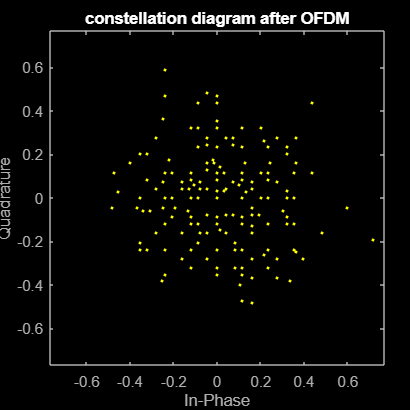

% plot ofdm signal

figure
scatterplot(timeDomainSymbols)
title('constellation diagram after OFDM');

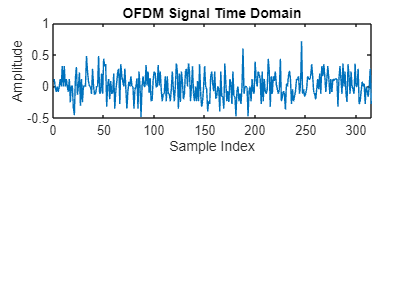


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(timeDomainSymbols));
title('OFDM Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

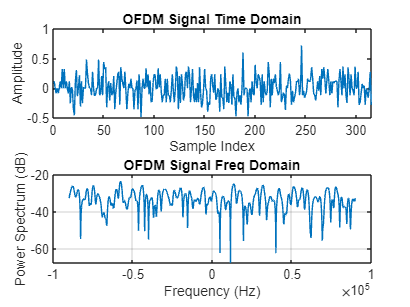


[pxx,f] = pspectrum(timeDomainSymbols,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('OFDM Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

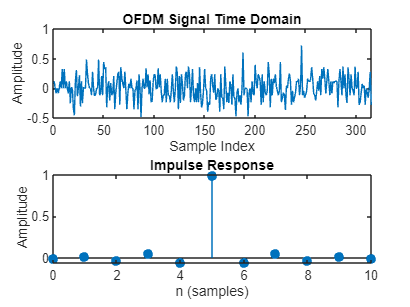

%upsampling
L = 1;  % Upsampling factor
rolloff = 0.25;  % Roll-off factor for the RRC filter
span = 10;  % Filter span in symbols

txSignalUpsampled = upsample(timeDomainSymbols, L);

rrcFilter = rcosdesign(rolloff, span, L);
impz(rrcFilter)

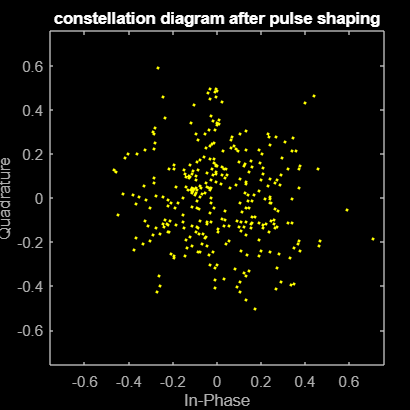


txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');

figure
scatterplot(txSignalShaped)
title('constellation diagram after pulse shaping');

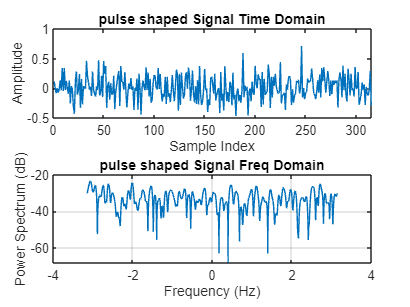


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(txSignalShaped));
title('pulse shaped Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(txSignalShaped);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('pulse shaped Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

% %convert to 900 MHz
% Fc=900e6;
% Fs=2*180e3;
% t = (0:length(txSignalShaped)-1)' / Fs; % Time vector
% cosCarrier = cos(2 * pi * Fc * t);
% sinCarrier = sin(2 * pi * Fc * t);
% txPassband = real(txSignalShaped) .* cosCarrier - imag(txSignalShaped) .* sinCarrier;
% % Plot the time domain signal after upconversion
% figure;
% plot(t(1:length(txPassband)), txPassband); % Plot a segment for better visualization
% title('Passband Signal - Time Domain');
% xlabel('Time (s)');
% ylabel('Amplitude');
% %freq
% [pxx,f] = pspectrum(txSignalShaped,Fs);
% subplot(2,1,2);
% plot(f+Fc,pow2db(pxx))
% grid on
% title('pulse shaped Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')

## channel

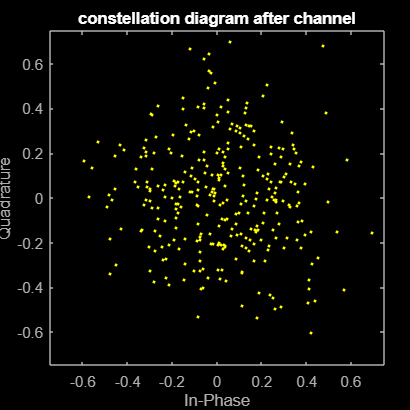

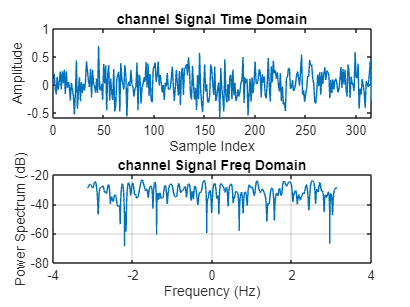

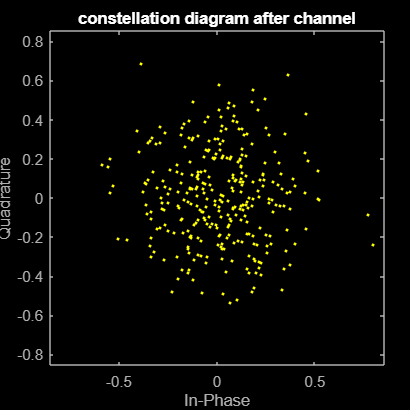

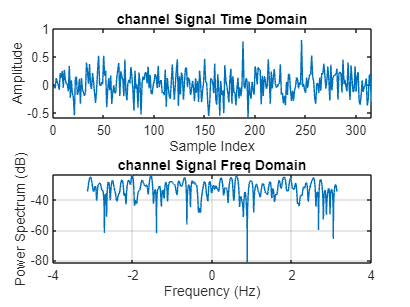

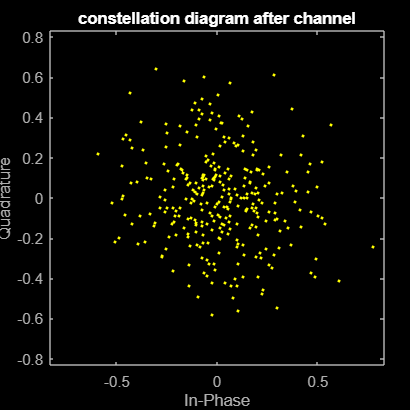

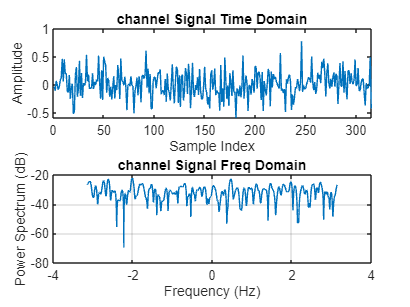

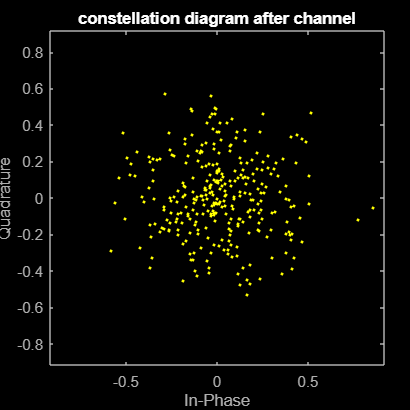

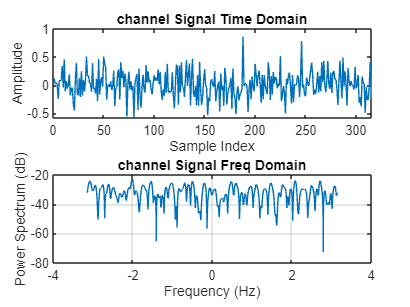

for counter=1:5


SNR=15+counter-1;%check filters, error rate is te hoog
% rxSignal=awgn(txSignalShaped,SNR);

rxSignal=awgn(txSignalUpsampled,SNR);
% rxSignal=txSignalShaped;

% Plot the time domain signal after channel
figure
scatterplot(rxSignal)
title('constellation diagram after channel');

% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(rxSignal));
title('channel Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(rxSignal);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('channel Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')


## receiver

% %downconvert to baseband
% I_component = rxSignal .* cosCarrier;
% Q_component = rxSignal .* sinCarrier;
% 
% filterOrder = 64;
% cutoffFreq = Fc / (2 * Fs); % Normalized cutoff frequency
% lpFilt = designfilt('lowpassfir', 'FilterOrder', filterOrder, 'CutoffFrequency', 0.5);
% 
% I_baseband = filtfilt(lpFilt, I_component);
% Q_baseband = filtfilt(lpFilt, Q_component);
% 
% rxBaseband = I_baseband - 1i * Q_baseband;

%matched filter
matchedFilter = rcosdesign(rolloff, span, L);
rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
rxSignalFiltered

rxSignalFiltered =    0.1841 - 0.2353i
  -0.0504 + 0.6508i
  -0.1676 - 0.0975i
   0.1389 + 0.3729i
  -0.0820 - 0.0934i
   0.0350 + 0.0414i
   0.2392 - 0.2298i
  -0.1142 + 0.3951i
   0.2741 + 0.2067i
  -0.0333 - 0.2977i


rxSignalFiltered =   -0.0015 - 0.0648i
  -0.0688 + 0.4027i
   0.1293 - 0.0110i
   0.0341 + 0.4742i
   0.0283 + 0.2428i
  -0.1060 - 0.0218i
   0.2294 - 0.3234i
   0.0874 + 0.3410i
   0.2631 + 0.1580i
  -0.0779 - 0.2703i


rxSignalFiltered =   -0.0251 - 0.1053i
  -0.1035 + 0.3800i
   0.0709 - 0.0417i
  -0.0037 + 0.5252i
  -0.0687 + 0.3217i
  -0.0641 - 0.0778i
   0.1014 - 0.4920i
   0.0841 + 0.3915i
   0.4752 + 0.1350i
   0.0059 - 0.1463i


rxSignalFiltered =    0.1122 - 0.1702i
   0.0237 + 0.3405i
   0.0359 - 0.0833i
   0.0123 + 0.3782i
  -0.2383 + 0.1857i
   0.0739 - 0.0792i
   0.0906 - 0.3168i
   0.0445 + 0.2778i
   0.3574 + 0.1114i
  -0.0932 - 0.3749i


rxSignalFiltered =    0.0195 - 0.1334i
  -0.1077 + 0.3652i
   0.0774 - 0.1216i
   0.0572 + 0.5101i
   0.0331 + 0.2391i
  -0.0823 + 0.0767i
   0.0697 - 0.4449i
   0.0229 + 0.3651i
   0.3588 + 0.2011i
  -0.0270 - 0.2373i


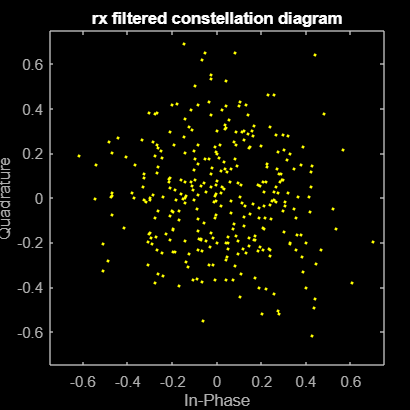

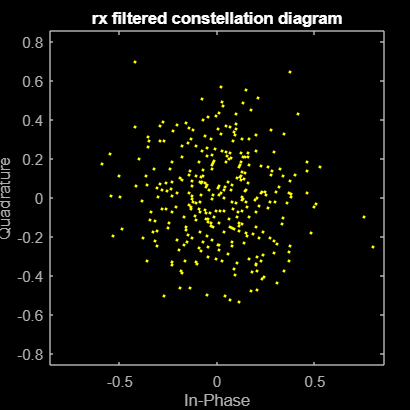

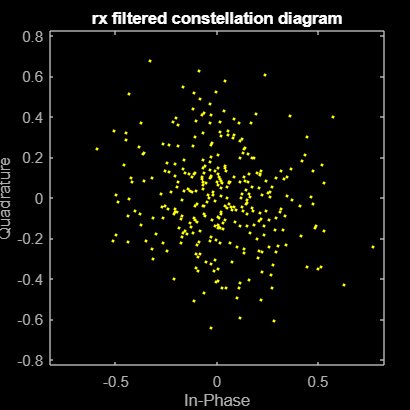

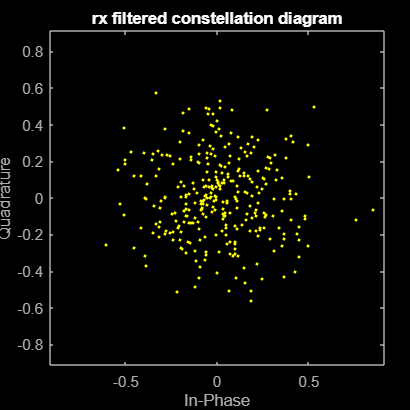

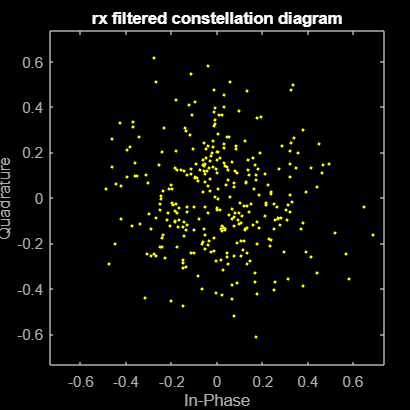


%downsample
% rxSignalDownsampled = downsample(rxSignalFiltered, L);

figure;
scatterplot(rxSignalFiltered);

title('rx filtered constellation diagram');

%cp
% rxSymbolsWithCP = reshape(rxSignalFiltered, [], numSym);
rxSymbolsWithCP = reshape(rxSignal, [], numSym);
rxSymbolsWithCP

rxSymbolsWithCP =    0.1977 - 0.1866i  -0.0214 + 0.1054i  -0.1009 - 0.3244i  -0.0806 + 0.2818i  -0.4804 + 0.0138i  -0.0261 + 0.5586i   0.0519 + 0.2485i   0.1738 - 0.1510i  -0.0328 + 0.5684i  -0.1797 - 0.0237i  -0.1204 + 0.6684i   0.3012 - 0.2225i  -0.2913 + 0.3723i  -0.2999 - 0.0123i  -0.2454 - 0.2164i  -0.2975 + 0.0340i   0.1682 - 0.0329i   0.3579 - 0.0343i   0.2507 - 0.4472i  -0.0585 + 0.1719i   0.1178 + 0.0096i
  -0.0588 + 0.6249i  -0.2814 - 0.3735i   0.0594 + 0.3089i  -0.1033 + 0.3000i  -0.3650 + 0.0748i   0.2622 + 0.0251i   0.4069 - 0.4687i   0.0351 + 0.1305i   0.2610 + 0.1515i  -0.2619 - 0.0424i   0.0060 - 0.3197i  -0.0628 - 0.3145i  -0.2308 - 0.0998i   0.1298 - 0.2210i   0.0305 - 0.0230i  -0.0299 + 0.0168i   0.2367 - 0.4316i   0.1177 + 0.1000i   0.2353 + 0.0402i   0.2797 + 0.2259i   0.3791 - 0.2242i
  -0.1728 - 0.0238i   0.0320 - 0.2099i   0.4201 - 0.1506i   0.0193 + 0.1051i   0.1040 + 0.2912i   0.0002 + 0.3742i  -0.0473 + 0.0512i  -0.1394 - 0.1804i   0.0204 - 0.2076i   0.3371 +

rxSymbolsWithCP =   -0.0102 - 0.0336i   0.3429 - 0.0383i  -0.1972 - 0.4144i   0.0212 + 0.0168i  -0.1470 - 0.0178i   0.0271 + 0.3704i   0.2129 + 0.4534i   0.0717 - 0.1146i   0.0184 + 0.2769i  -0.1800 - 0.1135i   0.0615 + 0.4883i   0.0696 - 0.1036i  -0.3625 + 0.0740i  -0.2476 - 0.0222i  -0.0672 + 0.0295i  -0.1731 - 0.1758i   0.1295 + 0.0703i   0.5245 - 0.0073i   0.0637 - 0.1387i  -0.1339 + 0.1866i   0.1494 - 0.0329i
  -0.0618 + 0.3924i  -0.2299 - 0.4795i  -0.1280 + 0.3005i  -0.0203 + 0.2051i  -0.1327 - 0.0312i   0.3205 + 0.1801i   0.2247 - 0.3902i   0.0851 + 0.0388i   0.2659 + 0.3221i  -0.0945 + 0.1170i   0.0357 - 0.2613i  -0.1779 - 0.3685i  -0.0594 + 0.0752i   0.0577 - 0.0851i  -0.0221 - 0.1289i  -0.1381 + 0.0469i   0.1043 - 0.5201i   0.1367 + 0.0815i   0.3296 + 0.1244i   0.4498 + 0.2322i   0.2291 - 0.3323i
   0.1237 + 0.0338i   0.0838 - 0.0488i   0.3986 - 0.2342i   0.0509 + 0.2058i   0.1360 - 0.0354i   0.1414 + 0.3238i   0.0253 + 0.2061i  -0.1463 - 0.1697i   0.4555 - 0.1584i   0.0733 +

rxSymbolsWithCP =   -0.0334 - 0.0750i   0.1745 + 0.0278i  -0.0138 - 0.3275i   0.0368 - 0.0409i  -0.2444 + 0.1377i  -0.0241 + 0.4237i   0.1810 + 0.2806i   0.2747 - 0.3489i   0.0359 + 0.3058i  -0.4201 - 0.1293i  -0.0615 + 0.6016i   0.3546 - 0.1494i  -0.5922 + 0.2197i  -0.1769 + 0.1450i  -0.1915 + 0.1693i  -0.1080 - 0.1098i  -0.0669 + 0.1166i   0.5032 - 0.0904i   0.2074 - 0.1833i  -0.0239 + 0.0617i   0.0021 - 0.0285i
  -0.1039 + 0.3660i  -0.2495 - 0.2526i   0.0417 + 0.2783i  -0.2481 + 0.3263i  -0.0062 + 0.1076i   0.1517 + 0.1420i   0.6093 - 0.4125i  -0.1681 + 0.1252i   0.3233 + 0.0278i  -0.0617 + 0.0431i  -0.1418 - 0.1772i  -0.3084 - 0.1224i  -0.0655 - 0.1803i   0.1017 - 0.1256i   0.0123 - 0.1976i  -0.0674 + 0.0931i   0.1014 - 0.4369i   0.0593 + 0.0961i   0.3816 + 0.0603i   0.4215 + 0.2164i   0.3004 - 0.5458i
   0.0691 + 0.0032i  -0.0456 - 0.2212i   0.5366 - 0.1276i   0.2599 + 0.0757i  -0.0964 + 0.3040i  -0.0067 + 0.1465i  -0.0509 + 0.2117i  -0.1099 + 0.0324i   0.2881 - 0.0706i   0.3938 +

rxSymbolsWithCP =    0.1178 - 0.1428i   0.1932 + 0.2116i  -0.1104 - 0.4243i  -0.1673 + 0.1927i  -0.3703 + 0.0562i  -0.0804 + 0.2904i  -0.1331 + 0.3464i   0.2336 - 0.1373i  -0.0228 + 0.3797i  -0.3601 - 0.2139i  -0.0075 + 0.4610i   0.2055 - 0.0616i  -0.5123 + 0.3593i  -0.2517 - 0.0790i  -0.0924 + 0.2499i  -0.2888 - 0.1701i   0.0021 + 0.1440i   0.3973 - 0.1850i   0.0757 - 0.1997i  -0.2316 + 0.2296i   0.0003 - 0.0051i
   0.0239 + 0.3224i  -0.1842 - 0.2509i   0.0860 + 0.4325i   0.0564 + 0.4140i  -0.0630 + 0.0465i   0.0691 - 0.1372i   0.3591 - 0.4142i  -0.1115 - 0.0072i   0.3623 + 0.2144i   0.1440 + 0.1547i  -0.0427 - 0.3824i  -0.0872 - 0.2736i  -0.1210 - 0.3991i   0.1546 + 0.0307i  -0.1569 - 0.0875i  -0.1830 + 0.0047i   0.1690 - 0.4498i   0.1690 + 0.1916i   0.4267 - 0.0418i   0.4905 + 0.3108i   0.1815 - 0.4725i
   0.0459 - 0.0431i  -0.0503 - 0.0050i   0.5081 - 0.0287i   0.1433 + 0.1120i  -0.0375 + 0.4469i  -0.1003 + 0.2024i   0.0448 + 0.0408i  -0.2630 - 0.1753i   0.3215 - 0.0770i   0.4667 +

rxSymbolsWithCP =    0.0115 - 0.0995i   0.1576 + 0.0497i   0.0891 - 0.3244i  -0.0267 + 0.1971i  -0.3628 + 0.1214i  -0.1219 + 0.2931i   0.0621 + 0.1404i   0.2912 - 0.1917i  -0.0224 + 0.4184i  -0.1573 - 0.2626i   0.1698 + 0.4498i   0.2854 - 0.0470i  -0.3453 + 0.0852i  -0.3275 + 0.0791i  -0.2750 + 0.1424i  -0.2712 - 0.2171i   0.1076 + 0.2277i   0.3304 - 0.3231i   0.1337 - 0.2464i  -0.0535 + 0.0881i   0.1345 + 0.1040i
  -0.1049 + 0.3411i  -0.3063 - 0.4144i   0.0125 + 0.2763i  -0.0194 + 0.3150i   0.0569 - 0.0043i   0.2307 + 0.0578i   0.3721 - 0.3700i   0.0512 + 0.1142i   0.3835 + 0.2687i  -0.0353 + 0.1476i  -0.0279 - 0.2389i  -0.0899 - 0.3094i  -0.0835 - 0.1737i   0.0859 - 0.0622i   0.0232 - 0.1293i  -0.1919 + 0.0980i   0.0875 - 0.3670i   0.0857 + 0.0126i   0.4302 + 0.0944i   0.4511 + 0.1246i   0.1948 - 0.3850i
   0.0719 - 0.0712i   0.1416 - 0.0021i   0.5944 - 0.3172i   0.2084 + 0.0811i   0.1917 + 0.3300i   0.0325 + 0.1599i   0.0379 + 0.2829i  -0.3267 - 0.2314i   0.2513 - 0.1277i   0.3866 +

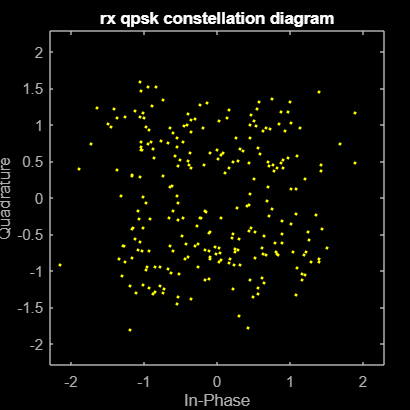

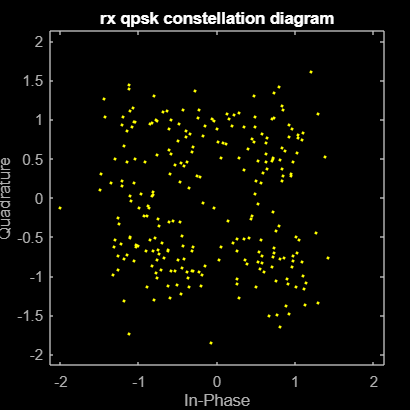

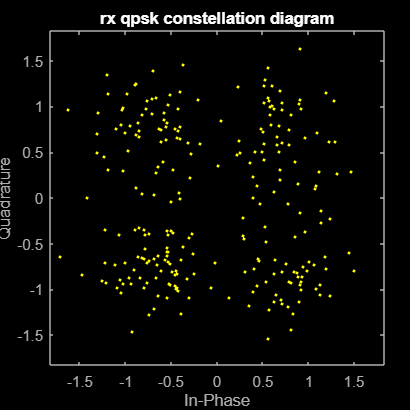

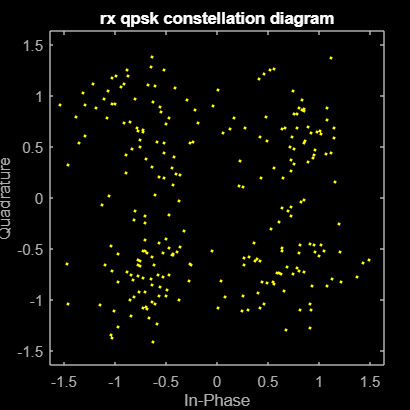

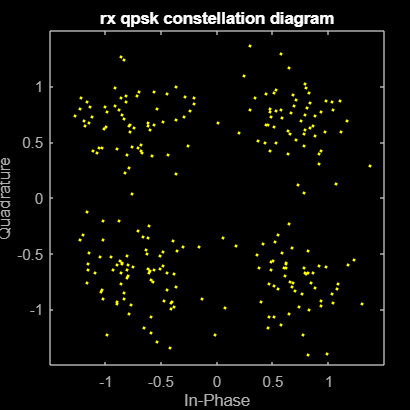

rxSymbols = rxSymbolsWithCP(cpLen+1:end, :);%remove cp from top of matrix (cplen +2 because matlab takes from the next sample to the end)
%fft
rxSymbolsFreq = fft(rxSymbols, numSC);% fft to freq domain
%qpsk
rxQPSKSymbols = rxSymbolsFreq(:);
demodulatedBits = zeros(length(rxQPSKSymbols)*2, 1);
figure;
scatterplot(rxQPSKSymbols);

title('rx qpsk constellation diagram');
% Demodulate QPSK symbols to bits
for k = 1:length(rxQPSKSymbols)
    [~, idx] = min(abs(rxQPSKSymbols(k) - symbolMap));
    demodulatedBits(2*k-1:2*k) = de2bi(idx-1, 2, 'left-msb');
end

errors=sum(demodulatedBits'~=messageBits(1:dataLength)')

errors = 29

errors = 12

errors = 8

errors = 9

errors = 4

nbiot_ber(counter)=errors/dataLength

nbiot_ber = 0.0575

nbiot_ber =     0.0575    0.0238


nbiot_ber =     0.0575    0.0238    0.0159


nbiot_ber =     0.0575    0.0238    0.0159    0.0179


nbiot_ber =     0.0575    0.0238    0.0159    0.0179    0.0079



symbolRate=samplingRate/SPS

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

bitRate =  2*12*symbolRate

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

EbN0_sim(counter)=SNR*samplingRate/bitRate

EbN0_sim = 7.5000

EbN0_sim =     7.5000    8.0000


EbN0_sim =     7.5000    8.0000    8.5000


EbN0_sim =     7.5000    8.0000    8.5000    9.0000


EbN0_sim =     7.5000    8.0000    8.5000    9.0000    9.5000



SNR_linear = 10^(SNR / 10);
Eb_N0(counter) = (SNR_linear * samplingRate) / bitRate

Eb_N0 = 15.8114

Eb_N0 =    15.8114   19.9054


Eb_N0 =    15.8114   19.9054   25.0594


Eb_N0 =    15.8114   19.9054   25.0594   31.5479


Eb_N0 =    15.8114   19.9054   25.0594   31.5479   39.7164


end

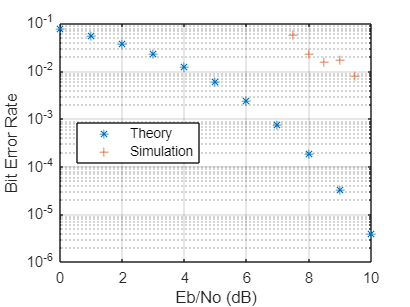

%ber
%https://nl.mathworks.com/help/releases/R2023a/comm/ug/analytical-expressions-used-in-berawgn-function-and-bit-error-rate-analysis-app.html
EbN0=(0:10);
ber=berawgn(EbN0,"psk",4,"nondiff");
figure
semilogy(EbN0',ber,'*')
hold on
semilogy(EbN0_sim',nbiot_ber,'+')
legend({'Theory','Simulation'},'Location','best')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
grid on